# [Cascade Classifier](https://apmonitor.com/pds/index.php/Main/CascadeClassifier)

Computer vision is how computers automate tasks that mimic human response to visual information. Image features such as points, edges, or patterns are used to identify an object in an image. A cascade classifier uses these visual cues as features to determine if an object is in the image, such as a face.

**Image Features**

A feature is a piece of information about the content of an image typically about whether a certain region of the image has certain properties. Features can be identified by color, shape, or size of the object.

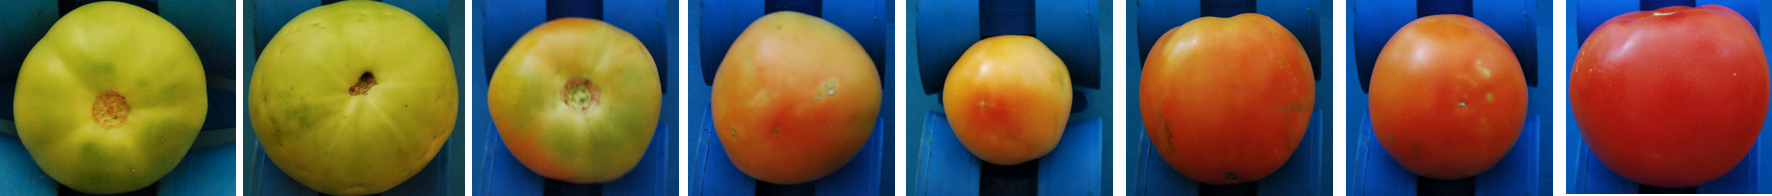

Features may also be characteristics of the general neighborhood or specific to a small region. Changes from frame to frame in image sequences may also be important features to detect a moving object relative to the surroundings. More broadly a feature is any piece of information which is relevant for solving the computational task related to a certain application. This is the same sense as a feature in machine learning and pattern recognition generally, though image processing has a very sophisticated collection of features. The feature concept is very general and the choice of features in a particular computer vision system may be highly dependent on the specific problem at hand.

- Harris Corner

- Local Binary Pattern (LBP)

- SIFT (Scale Invariant Feature Transform)

- Histogram of Oriented Gradient (HoG)

- SURF (Speeded Up Robust Feature) inspired by SIFT

- FAST (Features from Accelerated Segment Test)

- SUSAN (Smallest Univalue Segment Assimilating Nucleus)

- BASIS (BAsis Sparse-coding Inspired Similarity)

- SYBA (SYthetic BAsis Functions)

**Haar-like Features**

A [**Haar-like feature**](https://en.wikipedia.org/wiki/Haar-like_feature) considers adjacent rectangular regions at a specific location in a detection window, sums up the pixel intensities in each region and calculates the difference between these sums. This modified feature set is called 2-rectangle feature. Viola and Jones also defined 3-rectangle features and 4-rectangle features. The detection approach was proposed by Viola and Jones in 2001: [**Rapid Object Detection using a Boosted Cascade of Simple Features**](https://www.cs.cmu.edu/~efros/courses/LBMV07/Papers/viola-cvpr-01.pdf).

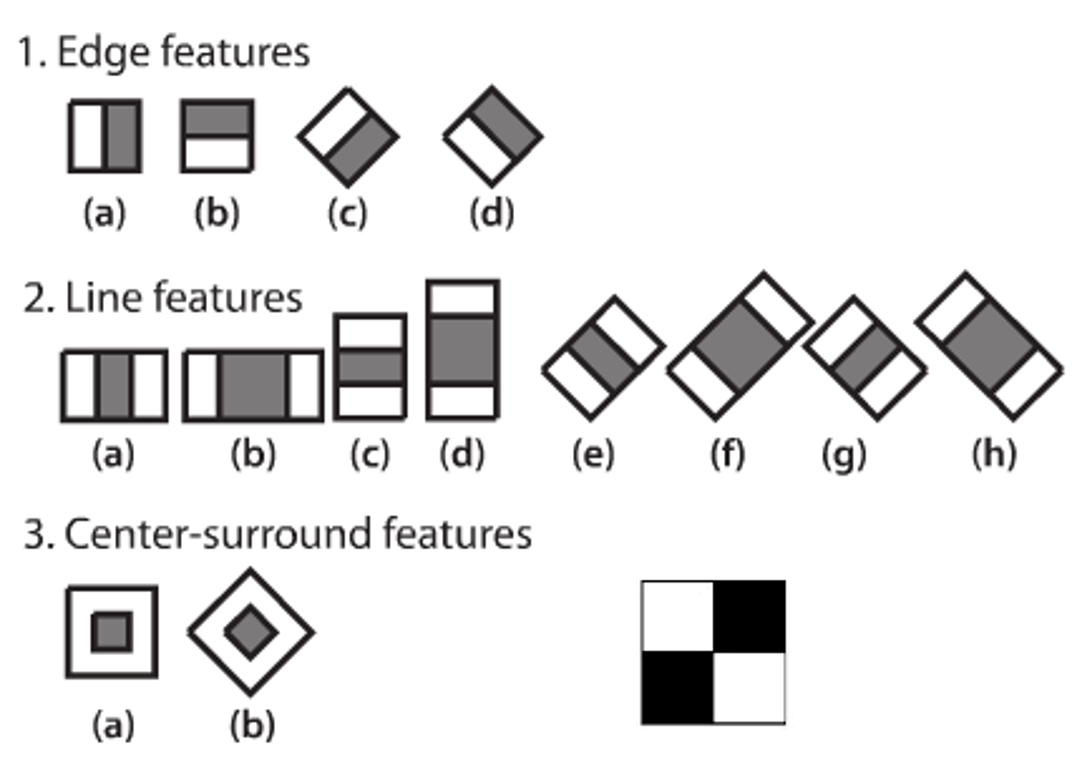

The values indicate certain characteristics of a particular area of the image. Each feature type can indicate the existence (or absence) of certain characteristics in the image, such as edges or changes in texture. For example, a 2-rectangle feature can indicate where the border lies between a dark region and a light region.

**Haar Cascade Classifier**

Cascading is a particular case of ensemble learning based on the concatenation of several classifiers, using all information collected from the output from a given classifier as additional information for the next classifier in the cascade. Unlike voting or stacking ensembles (multiexpert systems), cascading is a multistage method.

[**Cascading classifiers**](https://en.wikipedia.org/wiki/Cascading_classifiers) are trained with *positive* sample views of a particular object and arbitrary *negative* images of the same size. After the classifier is trained it can be applied to a region of an image and detect the object in question. To search for the object in the entire frame, the search window can be moved across the image and check every location for the classifier. This process is most commonly used in image processing for object detection and tracking, primarily facial detection and recognition.

Cascades are usually done through cost-aware [**AdaBoost**](https://apmonitor.com/pds/index.php/Main/AdaBoost). The sensitivity threshold (0.8 in our example) can be adjusted so that there is close to 100% true positives and some false positives. The procedure can then be started again for stage 2, until the desired accuracy/computation time is reached.

After the initial algorithm, it was understood that training the cascade as a whole can be optimized, to achieve a desired true detection rate with minimal complexity. Examples of such algorithms are RCBoost, ECBoost or RCECBoost. In their most basic versions, they can be understood as choosing, at each step, between adding a stage or adding a weak learner to a previous stage, whichever is less costly, until the desired accuracy has been reached. Every stage of the classifier cannot have a detection rate (sensitivity) below the desired rate, so this is a constrained optimization problem. To be precise, the total sensitivity is the product of stage sensitivities.

## Activity 1

Identify the faces in the photo with a Cascade Classifier for [**Face Detection**](https://apmonitor.com/pds/index.php/Main/FacialRecognition).

The following code uses functions from the [Computer Vision Toolbox](matlab:matlab.internal.addons.launchers.showExplorer('ErrorRecovery', 'identifier', 'VP', 'focused', 'vision.CascadeObjectDetector');). Be sure to download the toolbox before you begin. 

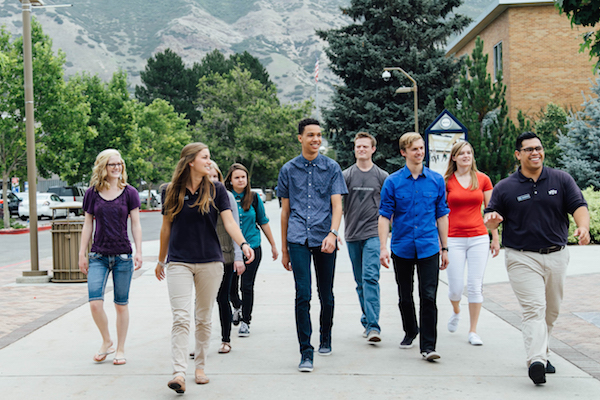

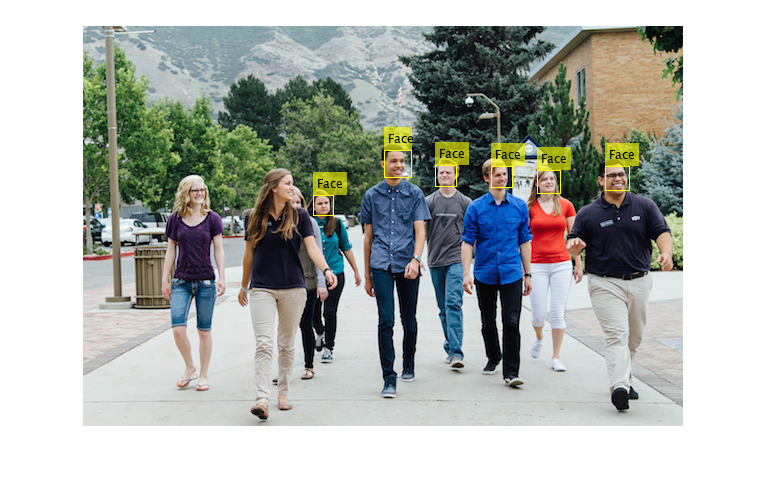

% download image as class.jpg
url = 'http://apmonitor.com/pds/uploads/Main/students_walking.jpg';
websave('class.jpg', url);

% read image
pixels = imread('class.jpg');

% load face cascade classifier
faceCascade = vision.CascadeObjectDetector();

% detect faces
bboxes = faceCascade(pixels);

% insert object of faces on photo
IFaces = insertObjectAnnotation(pixels,"rectangle",bboxes,'Face');

% Show image
figure
imshow(IFaces)

From this exercise, you can see that the face classifier does not detect every face in the photo.

## Activity 2

Run the face detection code that uses a pre-trained cascade classifier. Perform the following tests and note the relative effectiveness of face detection under the following scenarios:

- Look straight ahead at the camera

- Open and close mouth

- Look to the side

- Tilt head side to side

- Move close and far away from the camera

The following code was modified from this [link](https://www.mathworks.com/help/vision/ug/face-detection-and-tracking-using-live-video-acquisition.html).

The face detection can be improved by adjusting the parameters:

- **ScaleFactor**: Parameter specifying how much the image size is reduced at each image scale. A value of 1.05-1.20 is a good range to balance speed (higher numbers) and accuracy (lower numbers). Raising the value to 1.4+ may start to miss a face that is in between scaling sizes.

- **MinSize** and M**axSize**: Minimum and maximum face size in pixels. A good place to start is [30, 30] for the *minSize*. The default for *maxSize* is no upper limit.

The following code uses functions from the [Computer Vision Toolbox](matlab:matlab.internal.addons.launchers.showExplorer('ErrorRecovery', 'identifier', 'VP', 'focused', 'vision.CascadeObjectDetector');) again and utilizes your computer's webcam. If you're working on a desktop and want to use a USB webcam see [MATLAB Support Package for USB Webcams](https://www.mathworks.com/help/supportpkg/usbwebcams/index.html?s_tid=CRUX_lftnav). 

To stop the video, simply close the pop-up box.

% Create the face detector object.
faceDetector = vision.CascadeObjectDetector('FrontalFaceCART', ...
    'ScaleFactor', 1.2, ...
    'MinSize', [30, 30], ...
    'MaxSize', [200, 200]);

% Create the point tracker object.
pointTracker = vision.PointTracker('MaxBidirectionalError', 2);

% Create the webcam object.
cam = webcam();

% Capture one frame to get its size.
videoFrame = snapshot(cam);
frameSize = size(videoFrame);

% Create the video player object.
videoPlayer = vision.VideoPlayer('Position', [100 100 [frameSize(2), frameSize(1)]+30]);

runLoop = true;
numPts = 0;
frameCount = 0;

while runLoop
    % Get the next frame.
    videoFrame = snapshot(cam);
    videoFrameGray = im2gray(videoFrame);
    frameCount = frameCount + 1;

    if numPts < 10
        % Detection mode.
        bbox = faceDetector.step(videoFrameGray);

        if ~isempty(bbox)
            % Find corner points inside the detected region.
            points = detectMinEigenFeatures(videoFrameGray, 'ROI', bbox(1, :));

            % Re-initialize the point tracker.
            xyPoints = points.Location;
            numPts = size(xyPoints,1);
            release(pointTracker);
            initialize(pointTracker, xyPoints, videoFrameGray);

            % Save a copy of the points.
            oldPoints = xyPoints;

            % Convert the rectangle represented as [x, y, w, h] into an
            % M-by-2 matrix of [x,y] coordinates of the four corners. This
            % is needed to be able to transform the bounding box to display
            % the orientation of the face.
            bboxPoints = bbox2points(bbox(1, :));

            % Convert the box corners into the [x1 y1 x2 y2 x3 y3 x4 y4]
            % format required by insertShape.
            bboxPolygon = reshape(bboxPoints', 1, []);

            % Display a bounding box around the detected face.
            videoFrame = insertShape(videoFrame, 'Polygon', bboxPolygon, 'LineWidth', 3);

        end

    else
        % Tracking mode.
        [xyPoints, isFound] = step(pointTracker, videoFrameGray);
        visiblePoints = xyPoints(isFound, :);
        oldInliers = oldPoints(isFound, :);

        numPts = size(visiblePoints, 1);

        if numPts >= 10
            % Estimate the geometric transformation between the old points
            % and the new points.
            [xform, inlierIdx] = estgeotform2d(...
                oldInliers, visiblePoints, 'similarity', 'MaxDistance', 4);
            oldInliers    = oldInliers(inlierIdx, :);
            visiblePoints = visiblePoints(inlierIdx, :);

            % Apply the transformation to the bounding box.
            bboxPoints = transformPointsForward(xform, bboxPoints);

            % Convert the box corners into the [x1 y1 x2 y2 x3 y3 x4 y4]
            % format required by insertShape.
            bboxPolygon = reshape(bboxPoints', 1, []);

            % Display a bounding box around the face being tracked.
            videoFrame = insertShape(videoFrame, 'Polygon', bboxPolygon, 'LineWidth', 3);

            % Reset the points.
            oldPoints = visiblePoints;
            setPoints(pointTracker, oldPoints);
        end

    end

    % Display the annotated video frame using the video player object.
    step(videoPlayer, videoFrame);

    % Check whether the video player window has been closed.
    runLoop = isOpen(videoPlayer);
end

% Clean up.
clear cam;
release(videoPlayer);
release(pointTracker);
release(faceDetector);

## Further Training

Learn about the role of features in computer vision, how to label data, train an object detector, and track wildlife in video with the [**Computer Vision Onramp**](https://matlabacademy.mathworks.com/details/computer-vision-onramp/orcv) course. 